I = 0.5;
V1 = 100;
W1 = 0;
N1 = 1e3;
TTNB1 = 1000;
Hz = 1;
eqPulse = 1;
tP_Aim = 0.65;
searchPrecision = 1e-3;

if V1 == 0
    V = 40;
else
    V = V1;
end

if W1 == 0
    W = 0.9;
else
    W = W1;
end

if N1 == 0
    N = 10;
else
    N = N1;
end

if TTNB1 == 0
    TTNB = 360;
else
    TTNB = TTNB1;
end

V

V = 100

N

N = 1000

W

W = 0.9000

TTNB

TTNB = 1000

wave = genWvfm([Hz,W,N,eqPulse]);
dutyCycle = genDC(wave,TTNB);
tP = I*V*dutyCycle

tP = 22.8000

pulseTime = N/2 

pulseTime = 500

%plot(wave)


while tP < tP_Aim

    if V1 == 0
        V = V*(1+searchPrecision);
    else
        V = V1;
    end
    
    if W1 == 0
        W = W*(1+searchPrecision);
    else
        W = W1;
    end
    
    if N1 == 0
        N = 2*round(N*(1+searchPrecision)/2);
    else
        N = N1;
    end
    
    if TTNB1 == 0
        TTNB = TTNB*(1-searchPrecision);
    else
        TTNB = TTNB1;
    end
    
    wave = genWvfm([Hz,W,N,eqPulse]);
    dutyCycle = genDC(wave,TTNB);
    tP = I*V*dutyCycle;

end

while tP > tP_Aim

    if V1 == 0
        V = V*(1-searchPrecision);
    else
        V = V1;
    end
    
    if W1 == 0
        W = W*(1-searchPrecision);
    else
        W = W1;
    end
    
    if N1 == 0
        N = 2*round(N*(1-searchPrecision)/2);
    else
        N = N1;
    end
    
    if TTNB1 == 0
        TTNB = TTNB*(1+searchPrecision);
    else
        TTNB = TTNB1;
    end
    
    wave = genWvfm([Hz,W,N,eqPulse]);
    dutyCycle = genDC(wave,TTNB);
    tP = I*V*dutyCycle;

end




V

V = 100

N

N = 1000

W

W = 0.0200

TTNB

TTNB = 1000

tP

tP = 0.4000

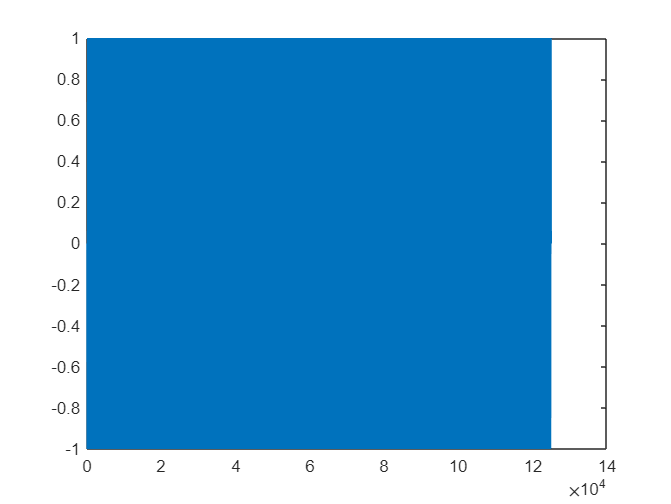

plot(wave)